# Mobile robot short Project

Given the kown workspace: Sensors_Data.mat, and  Enviroment.png

Answer the following question:

## Pose estimation given encoder data (10%)

Before start:

- Open the Simulink model EKF_Pose_estimation.slx and get familiar with: 'Where2Find_Code.pdf'. 

- Have a look to section See an animation of the file: 3_MR_SP_support.mlx 

Every thing is done, the exercise consist in compile in a mlx file all the concepts.

1.- Implement in this mlx file:

a) Pose_theoric, asumme no noise. (review **Mobile Robot Kinematics** folder)

b) Pose_estimation by adding noise in odometry. review **Pose uncertanty** folder)

c) Ricatti equation for estimating the covariance matrix representing the uncertanty in the robot pose. 

2.- Display in a figure:

a) x,y poses for both trajectories: theoric and estimated 

b) ellipses representing x,y uncertanty. Do it every 15-20 poses.

c) represent uncertanty in orientation by adding a isosceles triange in front of the robot the base 

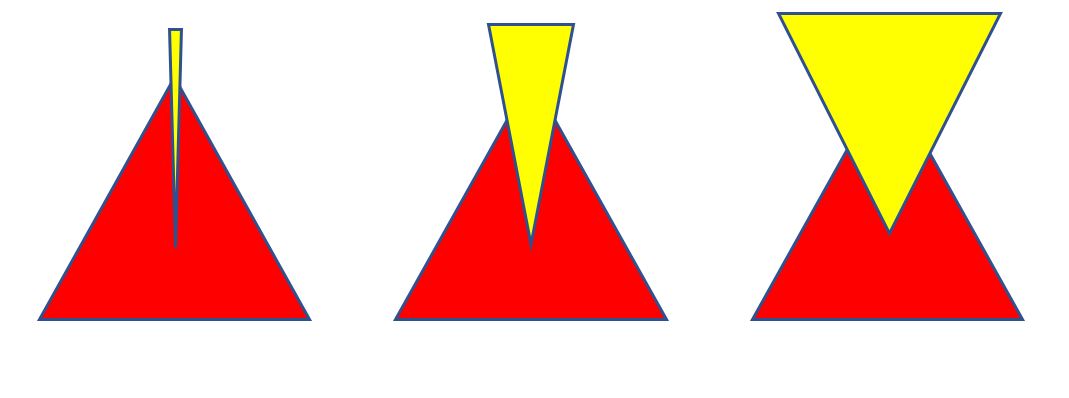

The robot will be represented by a triangle: Robot= [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1]

Record a movie of the robot moving along the corridor displaying both trajectories.

 See: help VideoWriter to get familiar with the matlab functions

clear
clf
load("Encoder_Data.mat")
load("Sensors_Data.mat")
%sim("EKF_Pose_estimation_1.slx");

S = W/2;
t=(0:Ts:Tf-Ts)';
Ratio = 100;

R_v = right_angular_speed;
L_v = left_angular_speed;

R_v(:,2) = R_v(:,2) .* r_w ./ 100;
L_v(:,2) = L_v(:,2) .* r_w ./ 100;

R_inc = R_v;
R_inc(:,2) = R_inc(:,2) .* Ts;

L_inc = L_v;
L_inc(:,2) = L_inc(:,2) .* Ts;

delta_d = (R_inc(:,2)+L_inc(:,2))/2;
delta_t = (R_inc(:,2)-L_inc(:,2))/W;

**a) Pose_theoric, asumme no noise.**

Initial_pose=transl(8.65,17.2,0)*trotz(-pi/2);
Pose(:,:,1)=Initial_pose;

 for i=1:length(delta_t)-1
    Pose(:,:,i+1)=Pose(:,:,i)*trotz(delta_t(i))*transl(delta_d(i),0,0);
    Position(:,i+1)=transl(Pose(:,:,i));
    Orientation(:,i+1)=tr2rpy(Pose(:,:,i));
 end

**b) Pose_estimation by adding noise in odometry**

ProcNoiseD=0.019^2; % is a variance. Stdmax<0.02
ProcNoiseTheta=0.003^2; % is a variance. Stdmax <0.0035
Ts=0.02;

V = [ ProcNoiseD 0; 0 ProcNoiseTheta];

noiseD = rand*V(1,1);
noiseTheta = rand*V(2,2);

Position_noise(:,1) = zeros(size(Position(:,1)));
Position_noise(:,2) = Position(:,2);

Orientation_n = zeros(3004,1);
Orientation_n(2) = Orientation(3,2);

 for i=3:length(delta_t)
    Position_noise(1,i)=Position_noise(1,i-1) + (delta_d(i)+noiseD)*cos(Orientation_n(i-1));
    Position_noise(2,i)=Position_noise(2,i-1) + (delta_d(i)+noiseD)*sin(Orientation_n(i-1));
    Orientation_n(i)=mod(Orientation_n(i-1) + delta_t(i) + noiseTheta , 2*pi);
 end

Pose_noise(:,:,1) = Initial_pose;
 for i = 1:(length(t)-1)
    Pose_noise(:,:,i+1) = Pose_noise(:,:,i)*transl(Position_noise(1,i), Position_noise(2,i), 0) * trotz(Orientation_n(i));
 end


**c) Ricatti equation for estimating the covariance matrix representing the uncertanty in the robot pose.**

Pk(:,:,1) = eye(3) * 0.001;

for i = 1:(length(t)-1)
    F_x = [1 0 -delta_d(i)*sin(Orientation(i));...
       0 1  delta_d(i)*cos(Orientation(i));...
       0 0 1];
    F_v = [cos(Orientation(i)) 0;....
       sin(Orientation(i)) 0;...
       0 1];
    Pk(:,:,i+1) = F_x*Pk(:,:,i)*F_x' + F_v*[V(1) 0;0 V(2)]*F_v'; 
end

**a) x,y poses for both trajectories: theoric and estimated**

figure
I = imread('Enviroment.png');
x_img = [0 35.9];
y_img = [23.31 0];
image(I, 'XData', x_img, 'YData',y_img);
axis xy
grid on
title('trajectory')
xlabel('X [m]')
ylabel('Y [m]')
hold on

plot(Position(1,2:end), Position(2,2:end), 'b');
plot(Position_noise(1,2:end), Position_noise(2,2:end), 'r');

**b) ellipses representing x,y uncertanty. Do it every 15-20 poses**

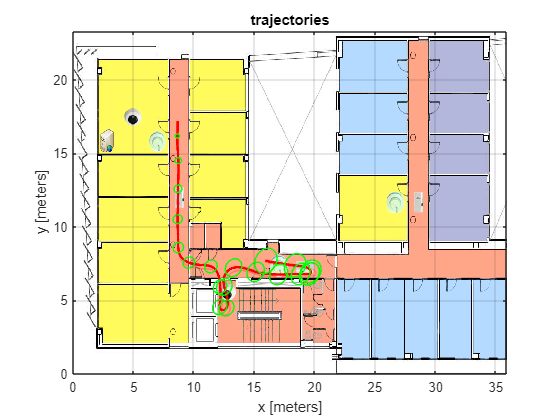

image(I,'XData',x_img,'YData',y_img,"AlphaData",0.75);
axis xy
hold on
    plot( ...
        Position(1,2:end), ...
        Position(2,2:end), ...
        'k', ...
        'Color','r', ...
        "LineWidth",2 ...
    )
    title('trajectories'); xlabel ('x [meters]'); ylabel ('y [meters]')
    for i=1:length(delta_t)
        if (mod(i,150)==0)
            plot_ellipse( ...
                Pk(1:2,1:2,i), ...
                [Position(1,i), Position(2,i)], ...
                'g'...
            );
        end
    end
hold off

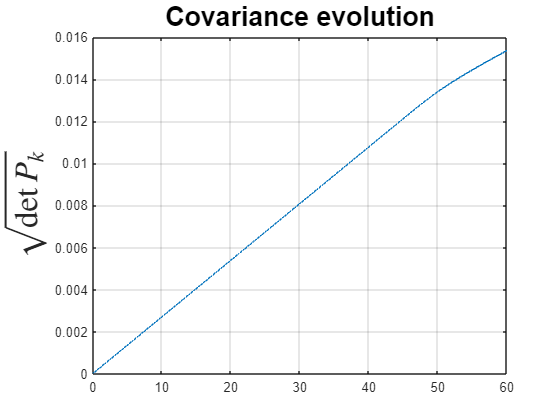


for i=1:3001;
    a(i)=sqrt(det(Pk(:,:,i)));
end
figure
plot((0:0.02:60), a)
title ('Covariance evolution',"FontSize",20)
ylabel('$\sqrt {\det {P_k}}$','Interpreter',"latex","FontSize",25)
grid on

**c) represent uncertanty in orientation by adding a isosceles triange in front of the robot the base**

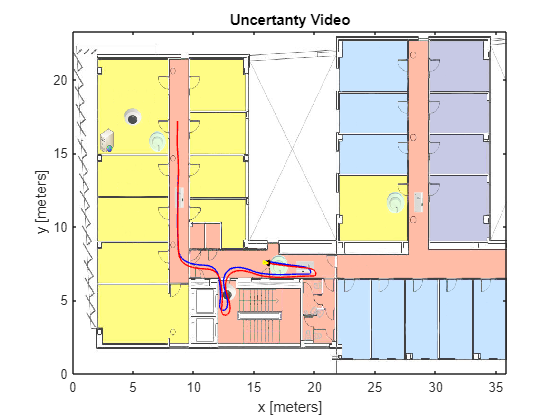

Robot= [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1]';
Triangle = [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1];

% video = VideoWriter('2c_uncertanty_triangle.avi');
% video.FrameRate = 45;
% video.Quality = 100;
% open(video);

image(I,'XData',x_img,'YData',y_img,"AlphaData",0.75);
axis xy
hold on
plot(Position(1,2:end), Position(2,2:end), 'b');
title('Uncertanty Video'); xlabel ('x [meters]'); ylabel ('y [meters]')
plot(Position_noise(1,2:end), Position_noise(2,2:end), 'r');
speed = 5;
r_patch=[];
t_patch=[];

for i=2:(length(t)-1)
        k_m=mod(i,speed);
        if k_m==0
            
            delete(r_patch);
            delete(t_patch);

            Triangle_uncertancy = Triangle;

            e = Pk(:, :, i);
            aux1 = Triangle_uncertancy(3, 2) * det(e(1:2, 1:2));
            aux2 = Triangle_uncertancy(1, 2) * det(e(1:2, 1:2));
            Triangle_uncertancy(3, 2) = aux1;
            Triangle_uncertancy(1, 2) = aux2;


            Robot_pose=transl(Position_noise(1,i),Position_noise(2,i),0)*trotz(Orientation_n(i));
            Robot_tr=Robot_pose*Robot; % moving the robot 
            triangle_tr=Robot_pose*transl(0.5,0,0)*trotz(pi)*Triangle_uncertancy';
            axis([0 35.9 0 23.31]);

            r_patch = patch(Robot_tr(1,:), Robot_tr(2,:),'red');
            t_patch = patch(triangle_tr(1,:), triangle_tr(2,:), 'yellow','FaceAlpha',.80, 'EdgeColor', 'yellow');
            %pause(0.01);
            
            % frame=getframe(gcf);
            % writeVideo(video,frame);
        end
end
hold off

%close(video);

## Mapping (10%)

Make a movie of laser data in Robot reference frame. See the video  of ATENEA: [Movie of the Laser Data seen in Robot Reference FrameURL](https://atenea.upc.edu/mod/url/view.php?id=3257292)

Make a video of laser data in Wordl Reference frame. Use here the code of the last TODO Lab about laser data. 

Display laser data every 2.5 m and erasing the previous walls after 200ms for better understanding.

See the video: '3_mapping.mp4' for inspiration

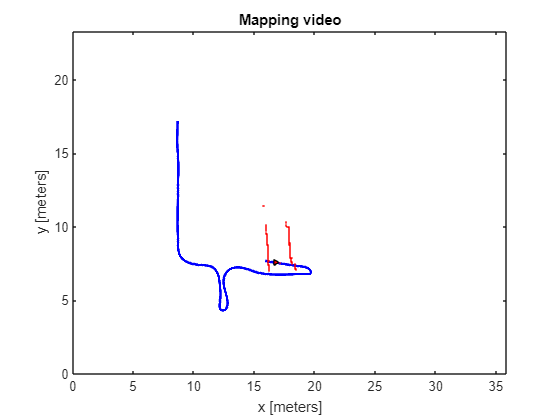

laser_data = polar_laser_data(:,2:683)/1000;

n_data = size(laser_data,2);
n_sampl = size(laser_data, 1);

plot_act = [];
laser_R = [];
laser_points = [];
points_plot = [];

ang_res = 0.3515;
ang = [1:length(laser_data)]*ang_res - 30;
ang = ang * pi/180;

[x,y] = pol2cart(ang, laser_data);
T_R_L = transl(0.6,0,0);

%set up video
% video_map = VideoWriter('3_Mapping.avi');
% video.FrameRate = 45;
% video.Quality = 100;
% open(video_map);

title('Mapping video'); xlabel ('x [meters]'); ylabel ('y [meters]')

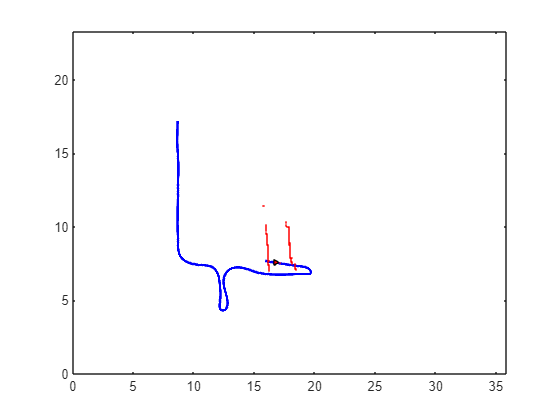

plot( ...
        Position(1,2:end), ...
        Position(2,2:end), ...
        'k', ...
        'Color','b', ...
        "LineWidth",2)
hold on
r_patch=[];
j = 1;
for i = 2:(length(t)-1)/20.1610738

    delete(plot_act);
    delete(r_patch);

    pos = i * 20;

        laser_points(:,:,i) = [x(i,:);y(i,:);zeros(1,n_data);ones(1,n_data)];
    %laser_points(:,:,i) = laser_points(:,:,i) * transl(Position(:,j))* T_R_L;

        points_plot(:,:,i) = transl(Pose(1,4,pos),Pose(2,4,pos),Pose(3,4,pos)) * T_R_L * laser_points(:,:,i);
        axis([0 35.9 0 23.31]);


        plot_act=scatter( ...
            points_plot(1,:,i), ...
            points_plot(2,:,i), ...
            1, ...
            'red', ...
            'filled' ...
        );

    Robot_pose=transl(Position(1,pos),Position(2,pos),0)*trotz(Orientation(pos));
    Robot_tr=Robot_pose*Robot; % moving the robot
    r_patch = patch(Robot_tr(1,:), Robot_tr(2,:),'red');

    %frame=getframe(gcf);
    %writeVideo(video_map,frame);
end
hold off

%close(video_map);

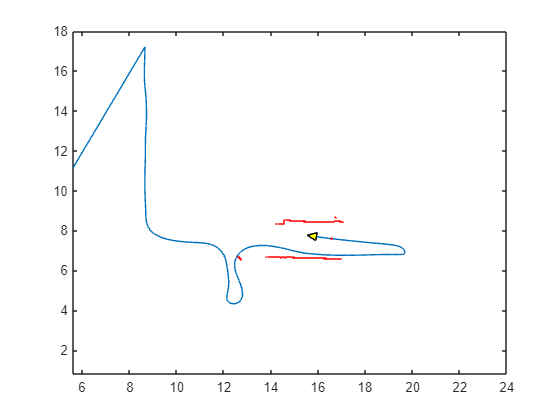

close all

Initial_position=transl(Initial_pose);
Initial_orientation=-pi/2;

x(1) = Initial_position(1);
y(1) = Initial_position(2);
o(1) = Initial_orientation;

for i=1:(length(t)-1)
    x(i+1) = x(i) + delta_d(i) * cos(o(i));
    y(i+1) = y(i) + delta_d(i) * sin(o(i));
    o(i+1) = o(i) + delta_t(i);
end



% Ladmarks poses
LandMark = [ 7.934 16.431 0 1;...
              9.583 16.431 0 1;...
              9.584 13.444 0 1;...
              9.584 10.461 0 1;...
              7.973 10.534 0 1;...
              7.934  7.547 0 1;...
              9.584  6.654 0 1;...
             13.001  6.525 0 1;...
             17.007  8.136 0 1]';

% axis tight manual 
% set(gca,'nextplot','replacechildren'); 
% video = VideoWriter('3_mapping.avi');
% open(video);
Robot = [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1];
visible = 0;
for k=1:3:(length(t)-1)
    clf
    plot(Position(1,:), Position(2,:), '-');
    xlim([5.6 24.0])
    ylim([0.8 18.0])
    hold on

    Robot_pose = transl(x(k), y(k), 0) * trotz(o(k));
    Robot_final = Robot_pose * Robot';

    rob = patch(Robot_final(1, :), Robot_final(2, :), 'y');
    
    if (mod(k, 6) == 1)
          clear x2 y2
        count = 1;
        m = size(polar_laser_data);
        i = ceil(k/20.1611);
        for j=1:(m(2)-1)
            if polar_laser_data(i, j) / 1000 > 0
                alpha = (j-1) * 0.3515;
                alpha = o(20 * (i-1) + 1) - 120 * pi/180 + alpha * pi/180;
                x2(count) = x(20 * (i-1) + 1) + (polar_laser_data(i, j) / 1000) * cos(alpha);
                y2(count) = y(20 * (i-1) + 1) + (polar_laser_data(i, j) / 1000) * sin(alpha);
                count = count + 1;
            end
        end
    end

    % if mod(k, 20) == 0
    %     visible = 0;
    %     for i = 1:width(l_s_b)
    %         if visible == 0 && l_s_b(k, i) ~= 0
    %             P = LandMark(:, i);
    %             dist = sqrt( (x(k) - P(1))^2 + (y(k) - P(2))^2 );
    %             if dist <= 4
    %                 visible = 1;
    %             end  
    %         end
    %     end
    % end

    
    %if visible
        scatter(x2, y2, 1, '.', 'red');
    %end

    pause(0.01)
    
%     frame = getframe(gcf);
%     writeVideo(video, frame);
%     delete(rob);
end

## Occupancy grid (30%)

Use Breshehan algorithm to build the map. Do it only when Land Marks are avalaible and the trajectory have been corrected.

Use the idea behind the line tracing: Visit: https://es.wikipedia.org/wiki/Algoritmo_de_Bresenham

See: Mapping.mlx and '4_occupancy.mp4' for inspiration

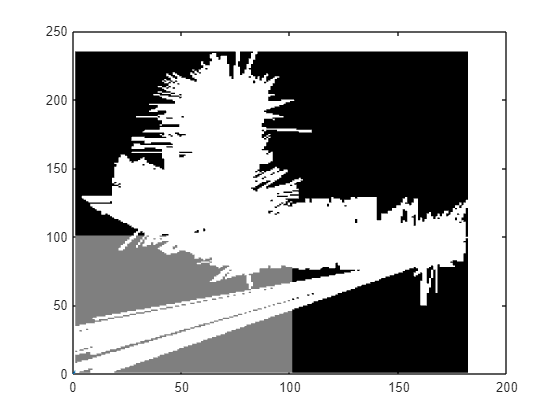

resolution = 10;
Map = ones(100, 100) * 0.5;
for p=20:20:(length(t)-1)
    %clear x2 y2 o2
    i = ceil(p/20.1611);
    count = 1;
    m = size(polar_laser_data);
    for j=1:(m(2)-1)
        if polar_laser_data(i, j) / 1000 > 0
            alpha = (j-1) * 0.3515;
            alpha = Orientation(20 * (i-1) + 1) - 120 * pi/180 + alpha * pi/180;

            %alpha = Orientation(20*(i-1)+1)- 120 * pi/180 + alpha * pi/180;
            Position1(1,count) = Position(1,20 * (i-1) + 1) + (polar_laser_data(i, j) / 1000) * cos(alpha);
            Position1(2,count) = Position(2,20 * (i-1) + 1) + (polar_laser_data(i, j) / 1000) * sin(alpha);
            Orientation1(count) = alpha;

            % x2(count) = x(20 * (i-1) + 1) + (polar_laser_data(i, j) / 1000) * cos(alpha);
            % y2(count) = y(20 * (i-1) + 1) + (polar_laser_data(i, j) / 1000) * sin(alpha);
            % o2(count) = alpha;
            count = count + 1;
        end
    end

    for j = 1:(count-1)
        P_w = transl(0, 0, 0) * trotz(0) * [Position1(1,j) Position1(2,j) 0 1]';
        [x y] = bresenham(Position(1,p)*resolution, Position(2,p)*resolution, P_w(1)*resolution, P_w(2)*resolution);
        L=length(x);
        for k=1:L
            % if x(k) > 0 && y(k) > 0
            %     if k == L
            %         Map(x(k), y(k)) = 0;
            %     else
            %         Map(x(k), y(k)) = 2;
            %     end
            % end
            if x(k) > 0 && y(k) > 0
                Map(x(k),y(k)) = 1;
            end
        end
    end

    h = pcolor(Map);
    h.EdgeColor = 'none';
    axis xy
    xlim([0 20*resolution]);
    ylim([0 25*resolution]);
    colormap(gray(3));
    pause(0.9)

%     frame = getframe(gcf);
%     writeVideo(video, frame);
end

%close(video);


## Driving the Robot (20%)

Based on what you learn in motion arquitectures use the Goint2point for driving the robot. Use 'frontend.m' function to introduce way points such to recreate a trajectory similar to the past section.

Make a video displaying both trajectories: estimated and theoric. Add the ellipses to visualize uncertanty.

Notice that in this exercise the trajectories appear as the robot moves.

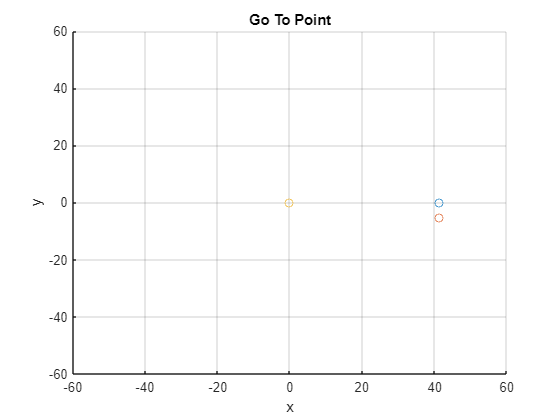

load("waypoints.mat");

startPose = [0,0,-pi]; % startPose [x y theta] 
goal = wp(:,2); % goal position

Kv = 0.9; % Velocity Gain. Units (m/s)/m = [1/s]
Kh = 4; % Head Gain. Units [1/s]
r = 0.1; % wheels radius
S = 0.26; % half of the distance between the wheels' center  
ts = 0.02;% sample time

currentPose = startPose;
stop = false;
figure
scatter(wp(1,46),goal);
hold on
scatter(startPose(1),startPose(2));
xlabel('x');
ylabel('y');
title('Go To Point')
grid
axis([-60 60 -60 60])



R_V= [0 -0.2 0 1;0.4 0 0 1;0 0.2 0 1]

R_V =          0   -0.2000         0    1.0000
    0.4000         0         0    1.0000
         0    0.2000         0    1.0000


R_F = [1,2,3];
hr=[];
count = 2;
% while (~stop)
%     delete (hr);
%     currentdiff = goal - currentPose([1,2])';
%     throttle = sqrt(currentdiff(1)^2 + currentdiff(2)^2);
%     if throttle < 2 && count < 46
%         goal = wp(:,count);
%         count = count + 1;
%     end
%     if throttle < 0.1 && isequal(goal,wp(:,46))%we can stop if distance error is less than 0.1
%         stop = true;
%     else
%         velocity = throttle *  Kv;
%         steering = atan2(currentdiff(2),currentdiff(1));
%         psi = angdiff(steering,currentPose(3))*Kh;
%         phi_l_r = I_kine(velocity,psi,r,S);
%         deltas = odo_vel(phi_l_r(1),phi_l_r(2),r,S,ts);
%         lastPose = currentPose;
%         currentPose = Pose_int(currentPose,[deltas(1),deltas(2)]);
%         pose = transl(currentPose(1),currentPose(2),0)* trotz(currentPose(3));
%         Robot_tr=pose*R_V';% moving the robot 
%         hr=patch(Robot_tr(1,:), Robot_tr(2,:),'b'); 
%         pause(0.05);
%         plot([lastPose(1),currentPose(1)],[lastPose(2),currentPose(2)],...
%         'LineStyle',"-","Color",'blue');
%     end
% end
% legend('goalPoint','startPoint','path');

## Localization (30%)

While driving the Robot in the last section Localize the Robot  by using the Similarity Transform. 

Visit again the folder 11_Localization for inspiration.

### Land Marks

Use the given Land Marks. They are known. They can be extracter from laser data, there are easy algorithms for finding they, like corner detection, etc ...

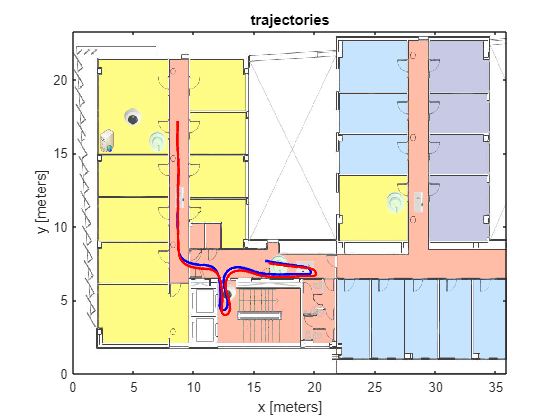

% % LandMark = [7.934 16.431 0 1;...
% %       9.583 16.431 0 1;...
% %       9.584 13.444 0 1;...
% %       9.584 10.461 0 1;...
% %       7.973 10.534 0 1;...
% %       7.934  7.547 0 1;...
% %       9.584  6.654 0 1;...
% %      13.001  6.525 0 1;...
% %      17.007  8.136 0 1];
% 
LandMark = [7.934 16.431 0 1;...
      9.583 16.431 0 1;...
      9.584 13.444 0 1;...
      9.584 10.461 0 1;...
      7.973 10.534 0 1;...
      7.934  7.547 0 1;...
      9.584  6.654 0 1;...
     13.001  6.525 0 1;...
     17.007  8.136 0 1]';
figure 
image(I,'XData',x_img,'YData',y_img,"AlphaData",0.75);
axis xy
hold on

    plot( ...
        Position(1,2:end), ...
        Position(2,2:end), ...
        'k', ...
        'Color','b', ...
        "LineWidth",2 ...
    )
    plot( ...
        Position_noise(1,2:end), ...
        Position_noise(2,2:end), ...
        'k', ...
        'Color','r', ...
        "LineWidth",2 ...
    )
    title('trajectories'); xlabel ('x [meters]'); ylabel ('y [meters]')

alpha = pi/16 % Rotate pi/16 rad --> 22.5 degrees;

alpha = 0.1963

m = 860; % Que posicion ????
Robot_pose = transl(Position(1,m), Position(2,m), 0)* trotz(Orientation(m));
%Robot_pose = transl(4,-2,0)* trotz(pi/4);
xyz_u = transl(Robot_pose);
RPY_u = tr2rpy (Robot_pose);
Robot_pose_teo = transl(Position(1,m)-1, Position(2,m)+8, 0)* trotz(Orientation(m)-pi/2);

%T_theoric=transl(2,2.5,0) * trotz(30, 'deg') % Theoric from encoders
Robot_pose_noise = transl(Position_noise(1,m), Position_noise(2,m), 0)* trotz(Orientation_n(m));

Robot_pose_noise=Robot_pose_teo*transl(1.3,0.8,0)*trotz(10,'deg')

Robot_pose_noise =     0.1736    0.9848         0    8.9825
   -0.9848    0.1736         0   14.4374
         0         0    1.0000         0
         0         0         0    1.0000


xy_n=transl(Robot_pose_noise);
RPY_n=tr2rpy(Robot_pose_noise);

A = [];
for i=1:size(LandMark, 2)
    A = [A;[LandMark(1,i),-LandMark(2,i),1,0]];
    A = [A;[LandMark(2,i),LandMark(1,i),0,1]];
end

for time = 3:length(polar_laser_data(:,1))

    Robot_pose = transl(Position_noise(1,time),Position_noise(2,time),0)*trotz(Orientation_n(time));
    xy_n = transl(Robot_pose);
    RPY_n = tr2rpy (Robot_pose);

    for i = 1:9
        z_lm(i,:) = z_laser(LandMark(:,i),xy_n,RPY_n(3));
        lxy_rf_u(:,i) = [z_lm(i,1)*cos(z_lm(i,2)) z_lm(i,1)*sin(z_lm(i,2))];
    end

end

Unrecognized function or variable 'z_laser'.


LandMark_n=[lxy_rf_u; zeros(1,9) ; ones(1,9)];
LandMark_u = Robot_pose_teo * LandMark_n;



%LandMark_u = Robot_pose * [lxy_rf_u; zeros(1,9); ones(1,9)];
scatter(LandMark(1,:), LandMark(2,:), 100, 'red', 'filled');
scatter(LandMark_u(1,:), LandMark_u(2,:),100, 'g','filled');

alpha = pi/16 % Rotate pi/16 rad --> 22.5 degrees
tx = 0.1; % Translate 
ty = 0.2;
RotzTxy = [cos(alpha), sin(alpha), tx;...
       -sin(alpha), cos(alpha), ty;...
       0,           0,          1]

LM_r=Robot_pose_teo*[LandMark];

A = [];
for i=1:size(LM_r, 2);
    A = [A;[LM_r(1,i),-LM_r(2,i),1,0]];
    A = [A;[LM_r(2,i),LM_r(1,i),0,1]];
end

B = [];%Build Matrix B
for i=1:size(LandMark_n, 2)
    B = [B; LandMark_n(1,i); LandMark_n(2,i)];
end

X = inv((A'*A))*A'*B
tx_ST = X(3)
ty_ST = X(4)
alpha_ST = atan2(X(2),X(1))
hold off



### Plot Land Marks 

hold on
sz = 100;
s=scatter(Lmk(:,1),Lmk(:,2),sz);
s.LineWidth = 0.6;
s.MarkerEdgeColor = 'b';
s.MarkerFaceColor = [0 0.5 0.5];

### Correct the noisy trajectory. 

Pay attention to the relationship of the variables

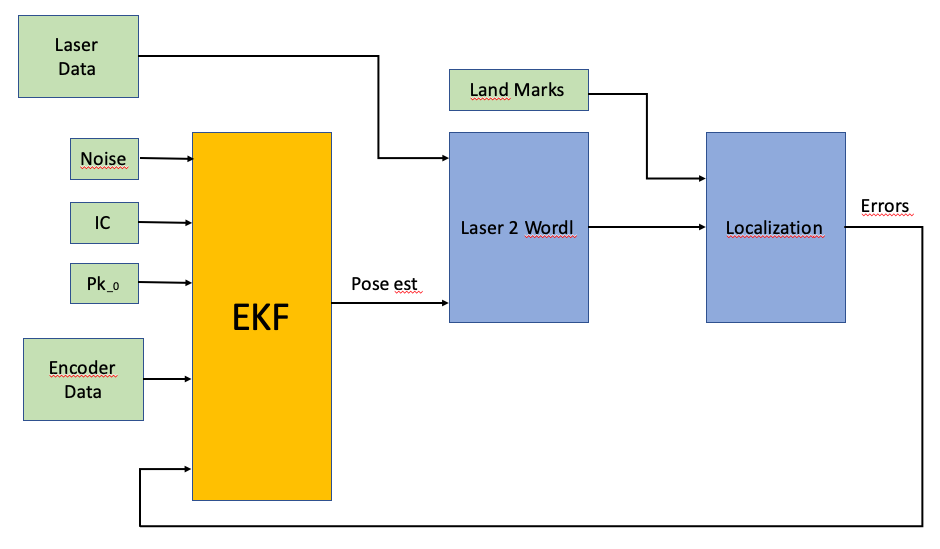

Update the estimated covarianze matrix by the sensor, knowing that the Laser scanner has and acuraccy 4 mm with a standard deviation of 0.2 mm.

1.- Display in a figure: the map, theoric trajectory (no noise) and the corrected trajectory. See: Expected_Localization.mp4

2.- Make a 'log' with the following columns:  estimated noisy pose, corrected position, number of Land-marks seen,  and the errors and the covariance matrix Pk.

LandMark_corr = transl(-tx_ST, -ty_ST, 0) * trotz(alpha_ST) * LandMark_u;
LandMark_corr = LandMark_corr(1:2, :);

% Pose_noise_o(:,:,1) = zeros(4,4);
% for i = 1:3004
%     Pose_noise_o(:,:,i) = [Pose_noise_o; ones(1,4)];
% end

%Pose_corr = transl(-tx_ST, -ty_ST, 0) * trotz(alpha_ST) * Pose_noise;

Position_corr = transl(-tx_ST, -ty_ST, 0) * trotz(alpha_ST) * [Position_noise; ones(1, length(Position_noise))];

% for i = 1:length(Position_noise)
%     Position_corr(:,:,i) = transl(-tx_ST, -ty_ST, 0) * trotz(alpha_ST) * [Position_noise(:,i); ones(1, length(Position_noise))];
% end


figure
% Display blueprint
image(I,'XData',x_img,'YData',y_img);
axis xy
hold on
grid on
% Display poses
plot(Position(1,2:end), Position(2,2:end), 'b');
plot(Position_noise(1,2:end), Position_noise(2,2:end), 'r');
plot(Position_corr(1,2:end), Position_corr(2,2:end), 'c');
% Display Landmarks
sz = 100;
scatter(LandMark(1,:), LandMark(2,:), 200, 'r','filled');
scatter(LandMark_u(1,:), LandMark_u(2,:), 200, 'g','filled');
scatter(LandMark_corr(1,:), LandMark_corr(2,:), sz, 'c','filled');
log2.time_stamp = t;             % Time stamp
log2.noiseD = noiseD;               % Estimated noisy pose
log2.noiseTheta = noiseTheta;
log2.corrected_pos = Pose_corr;  % Corrected position
log2.number_landmarks = 4;       % Number of Land-marks seen
log2.tx_ST = tx_ST;              % Errors
log2.ty_ST = ty_ST;
log2.alpha_ST = alpha_ST;
%log2.robot_error = Robot_error;

## Necessary Functions

**Inverse Kinematics**

I_kine = @(v_x, psi,r,S) ...
[(1/r)*v_x+ (1/r)*S*psi (1/r)*v_x-(1/r)*S*psi];
w_s=I_kine(1,0,0.1,0.26)

**Odometry**

odo_vel = @(phi_r, phi_l,r,S,ts) ...
[(1/2)*r*(phi_r+phi_l)*ts (r/(2*S))*(phi_r-phi_l)*ts];
odo_vel(1,1,0.1,0.26,0.02)

odo_cum = @(Delta_r, Delta_l,S) ...
[(1/2)*(Delta_r+Delta_l) (1/(2*S))*(Delta_r-Delta_l)];
odometry = odo_cum(-0.01,0.01,0.26)

**Pose Integration**

Pose_int=@(X_ant,odo) ...
[X_ant(1)+odo(1)*cos(X_ant(3)) ...
 X_ant(2)+odo(1)*sin(X_ant(3)) ...
 X_ant(3)+odo(2)];
Next_pose=Pose_int([0 0 0],odometry)

**Laser Measuring Land Mark**

z_laser=@(lm_xy,xy_r, th_r)...
    [sqrt((lm_xy(1)-xy_r(1))^2 +(lm_xy(2)-xy_r(2))^2) atan2((lm_xy(2)-xy_r(2)),(lm_xy(1)-xy_r(1)))-th_r]